1.

root = fzero(@kgy_24011189_func_1,1);
fprintf('x: %.4f\n', root);

x: 1.3606


[x_min, min_val] = fminbnd(@kgy_24011189_func_1, 0 ,4);
fprintf('최솟값: %.4f\n', x_min);

최솟값: 0.7101


전역에서 최소 증명

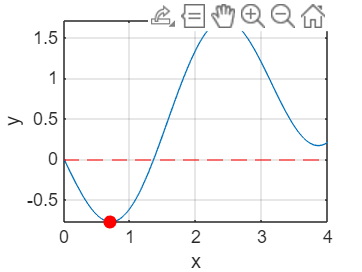

figure;

fplot(@kgy_24011189_func_1, [0 4])
grid on
hold on

yline(0, 'r--') 
xlabel('x')
ylabel('y')
plot(x_min, min_val, 'ro', 'MarkerFaceColor', 'r')

2.

h = 100;
v0= 50;
g = 9.81;

t = kgy_24011189_func_2(h, v0, g);

fprintf('도달시간: %.4f\n', t);

도달시간: 7.4612
도달시간: 2.7324


물체를 위로 던졌을 때 처음으로 높이 100m 에 도달한 시간은 2.7324s 이고 물체가 최고점에 도달했다가 중력 때문에 다시 떨어지면서 내려오는 길에 다시 한번 100m 를 통과한 시간은 7.4612s 이다.

3.

면적 A를 최소화하는 r값 계산

global V;
V = 10;

[R, A_min] = fminbnd(@kgy_24011189_func_3, 0.1, 10);
fprintf('R: %.4f\n', R);

R: 1.8901


상응하는 높이 h

h = (3 .* V) / (pi .* R.^2);
fprintf('h: %.4f\n', h);

h: 2.6730


r에 대한 A의 그래프 그려서 민감도 조사

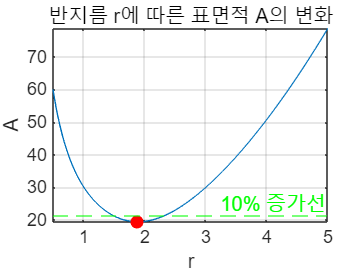

figure;

fplot(@kgy_24011189_func_3, [0.5 5])
grid on
hold on

title('반지름 r에 따른 표면적 A의 변화')
xlabel('r')
ylabel('A')
plot(R, A_min, 'ro', 'MarkerFaceColor', 'r')

A_target = A_min * 1.1;
yline(A_target, 'g--', '10% 증가선')


fprintf('10%% 증가: %.4f\n', A_target);

10% 증가: 21.3833



r_left  = fzero(@(r) kgy_24011189_func_3(r) - A_target, [0.5, R]); 
r_right = fzero(@(r) kgy_24011189_func_3(r) - A_target, [R, 5.0]);  

fprintf('10%% 증가 지점 (왼쪽 r): %.4f\n', r_left);

10% 증가 지점 (왼쪽 r): 1.4823


fprintf('10%% 증가 지점 (오른쪽 r): %.4f\n', r_right);

10% 증가 지점 (오른쪽 r): 2.3316


10% 증가한 면적의 최솟값은 약 21.3833 이고 이때 r의 값의 범위는 약 1.4823 ~ 2.3316 이다. 따라서 R은 최적값인 1.8901 에서 왼쪽으로 약 0.4, 오른쪽으로 약 0.5 까지 벗어날 수 있다.

4.

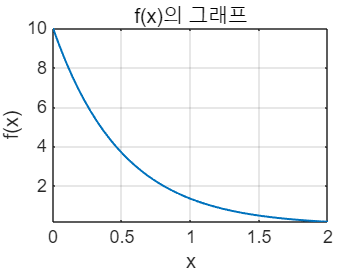

kgy_24011189_func_4 = @(x) 10 .* exp(-2 .*x);

figure;
fplot(kgy_24011189_func_4, [0, 2], 'LineWidth', 1);

grid on
title('f(x)의 그래프')
xlabel('x')
ylabel('f(x)')

5.

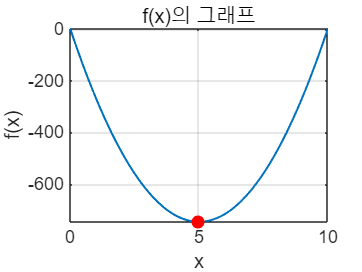

kgy_24011189_func_5 = @(x) 30 .* x .^ 2 - 300 .* x +4;
figure;
fplot(kgy_24011189_func_5, [0, 10], 'LineWidth', 1);
grid on
hold on
title('f(x)의 그래프')
xlabel('x')
ylabel('f(x)')
[x_min5, min_val5] = fminbnd(kgy_24011189_func_5, 0 ,10);
plot(x_min5, min_val5, 'ro', 'MarkerFaceColor', 'r')

fprintf('x: %.4f\n', x_min5);

x: 5.0000


fprintf('최솟값: %.4f\n', min_val5);

최솟값: -746.0000


6.

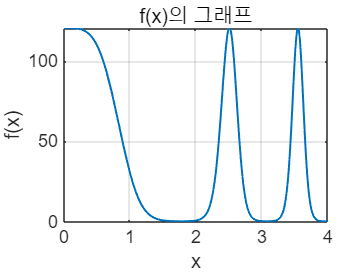

kgy_24011189_func_6a = @(z) 6 .* exp(z);
kgy_24011189_func_6b = @(y) 3 .* cos(y);
kgy_24011189_func_6c = @(x) x .^ 2;
kgy_24011189_func_6 = @(x) (kgy_24011189_func_6a(kgy_24011189_func_6b(kgy_24011189_func_6c(x))));

figure;
fplot(kgy_24011189_func_6 ,[0, 4], 'LineWidth', 1);

grid on
title('f(x)의 그래프')
xlabel('x')
ylabel('f(x)')